s = settings;
s.matlab.fonts.editor.normal.Name.PersonalValue = 'Space Grotesk';
s.matlab.fonts.editor.normal.Style.PersonalValue = {'plain'};
s.matlab.fonts.editor.title.Name.PersonalValue = 'Space Grotesk';
s.matlab.fonts.editor.heading3.Name.PersonalValue = 'Space Grotesk';
s.matlab.fonts.editor.heading2.Name.PersonalValue = 'Space Grotesk';
s.matlab.fonts.editor.heading1.Name.PersonalValue = 'Space Grotesk';
s.matlab.fonts.editor.code.Name.PersonalValue = 'JetBrains Mono';

Basic code for changing the normal text fonts and code fonts, along with their styles.

For more information, visit [matlab.font settings](https://in.mathworks.com/help/matlab/ref/matlab.fonts-settings.html).

I = imread("pout.tif");

Read an image into the workspace using the [imread](https://in.mathworks.com/help/matlab/ref/imread.html) function. The example reads one of the sample images included with the toolbox, an image of a young girl in a file named `pout.tif`, and stores it in an array named `I`. The `imread` function infers from the file that the graphics file format is Tagged Image File Format (TIFF).

I

I = 291×240 uint8 matrix
   107   108   107   106    99   101   102   107   107   103   112   164   200   197   170   182   213   214   212   197   137   112   110   109   112   110   107   105   106   106   107   109   108   106   106   106    99    98    99   101    99   102   103   105   103   119   147   205   204   209
   109   106   108   107   103   102   103   110   113   108   128   182   210   210   182   166   189   210   213   210   167   119   110   108   112   110   106   106   107   107   105   107   106   107   108   107   106   102    95   103   106   108   121   120   109   128   161   208   207   212
   107   106   110   110   106   107   107   120   133   133   125   151   181   189   175   151   159   204   210   212   189   137   119   107   110   110   107   108   108   107   106   106   106   105   106   108   107   105    98   103   128   150   164   137   121   133   169   208   210   215
   106   107   108   108   108   108   108   114   126   146   133   146

Displays the image as in intensity(0 to 255) of colour in each cell, whose count is decided by the resolution of the image. Notice that the image is in **greyscale**.

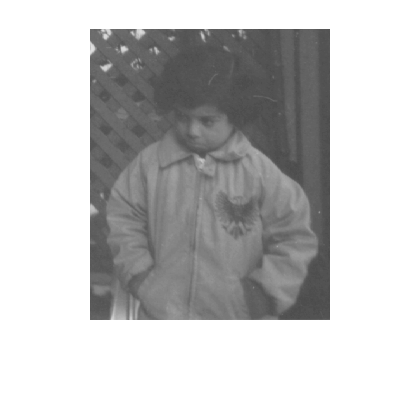

imshow(I);

Displays the image.

whos I

  Name        Size             Bytes  Class    Attributes

  I         291x240            69840  uint8              



Check how the **imread** function stores the image data in the workspace using the [whos](https://in.mathworks.com/help/matlab/ref/whos.html) function. You can also check the variable in the Workspace browser. The **imread** function returns the image data in the variable `I`, which is a 291-by-240 element array of uint8 data.

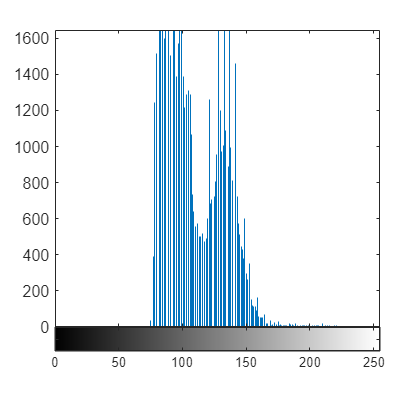

imhist(I)

View the distribution of image pixel intensities. The image **pout.tif** is a somewhat low contrast image. To see the distribution of intensities in the image, create a histogram by calling the [imhist](https://in.mathworks.com/help/images/ref/imhist.html) function. Notice how the histogram indicates that the intensity range  of the image is rather narrow. The range does not cover the potential  range of [0, 255], and the image is missing the high and low values that would result in good contrast.

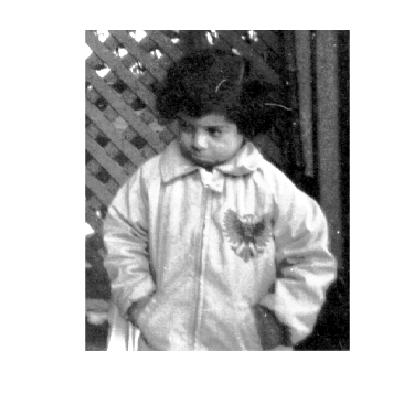

I2 = histeq(I);
imshow(I2)

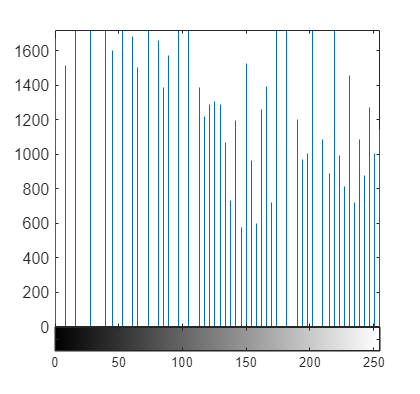

imhist(I2)

**Histogram equalization**, i.e., [histeq](https://in.mathworks.com/help/images/ref/histeq.html) function, spreads the intensity values over the full range of the image. This enhances the **contrast** of the image.

The **histeq** function transforms the grayscale image `I` so that the histogram of the output grayscale image I2 has 64 bins and is approximately flat.

imwrite(I2,"pout2.png");

Save/**write** the new image `I2` to a file using the [imwrite](https://in.mathworks.com/help/matlab/ref/imwrite.html) function. This example includes the extension **.png** in the filename, so the **imwrite** function writes the image to a file in Portable Network Graphics (PNG) format. (Other file formats can also be used) The new file will be saved to MATLAB folder in the **Documents** section of your computer.

imfinfo("pout2.png")

ans = struct with fields:
                  Filename: 'C:\Users\HP\OneDrive\Documents\MATLAB\pout2.png'
               FileModDate: '21-Oct-2023 20:24:58'
                  FileSize: 36938
                    Format: 'png'
             FormatVersion: []
                     Width: 240
                    Height: 291
                  BitDepth: 8
                 ColorType: 'grayscale'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: '21 Oct 2023 14:54:58 +00

Pretty much self - explanatory :) 